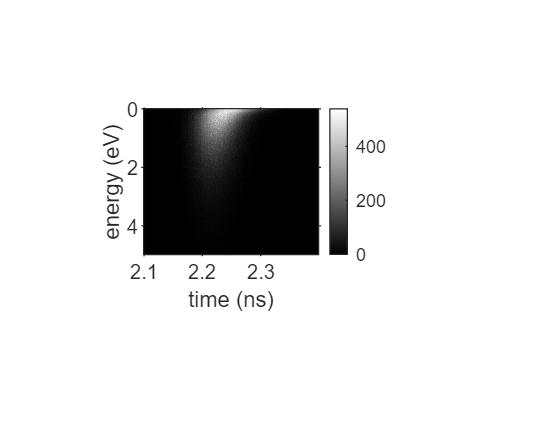

clear;
% Parameters
xBinSize = 0.3/200; % Size of each bin along the x-axis
yBinSize = 5/200; % Size of each bin along the y-axis
csvFile = 'output.csv'; % Your CSV file

% Read the CSV file
data = csvread(csvFile);

% Compute the x and y axis ranges
[nRows, nCols] = size(data); % Get the dimensions of the image
x = 2.1+(0:nCols-1) * xBinSize; % x-axis values
y = (0:nRows-1) * yBinSize; % y-axis values

% Display the image with specified axes
imshow(data, [], 'XData', x, 'YData', y);
%colormap(gray); % Apply grayscale colormap
colorbar; % Optional: Display a color scale
axis on; % Turn on the axes
xlabel('time (ns)');
ylabel('energy (eV)');
%title('Grayscale Image with Specified Axes');
daspect([4 80 1]);
axis tight;
set(gcf, 'Position', [1, 1, 1000, 800]); % [x, y, width, height]